# Data Initialization

Firstly, we load into a structure the data recorded by a person when doing forehands, backhands and walking/running.

clear
jo.forehand = load('forehand2.mat');
jo.backhand = load('backhand.mat');
jo.run_walk = load('run_walk.mat');
% jo.map = load('map.mat');


# Feature Extraction

For every 20 samples we extract a 6 valued vector contained the mean and standard deviations of the accelerometer data for X, Y and Z. axis. The sample window is overlapping, meaning that at each feature vector corresponds to the last 20 samples at a given momemnt. This could be extended to an 18 valued vector by using the angular velocity and orientation axis data.


fore_data = extract_features(jo.forehand)

fore_data =   16.199844899999999  16.962666100000000  17.852221249999999  18.841985500000000  20.009969150000000  20.627854250000006  20.712989750000002  19.788587050000000  17.832986200000001  16.834659699999996  20.116787000000002  20.453743800000002  21.136257000000004  21.443036549999999  21.395585199999999  16.454667399999998  13.748317800000001  13.531875400000001  14.271786750000000  15.017491049999999  15.379408399999999  14.864419299999998  14.254138400000002  13.489356300000001  13.317244199999999  15.399683749999999  16.442617450000000  16.547055250000000  17.275328300000002  17.012894050000000  13.182210000000001  13.223127399999999  13.378826149999998  14.198753600000000  15.103292600000000  15.868785749999997  15.942425099999998  15.164560150000000  13.861504849999999  16.919967249999996  17.689876250000001  18.268565400000000  18.352323699999999  18.260137899999997  17.537560500000001  15.288622199999997  14.479943849999998  14.891677649999997  15.666219499999997  16.409

back_data = extract_features(jo.backhand)

back_data =    9.953626500000000  10.486638099999999  11.051795349999999  11.499282300000001  12.025146250000001  12.341139150000000  12.494300650000000  12.628429199999998  12.587526799999997  12.249073099999997  12.090956899999998  12.141888450000000  12.458487599999996  13.303225949999998  12.478867699999997  11.176912599999998  10.960283049999997  10.909246649999996  10.807405949999998  10.719067149999997  10.843241399999997  11.166426849999995  11.325246599999996  11.315127649999997  11.158575699999998  11.142409300000001  11.097989150000000  11.199612850000001  11.478101200000001  12.375155749999999  13.936596200000000  13.486886399999999  12.882114000000001  11.429953749999999  11.598712849999998  12.067665149999998  12.608535450000000  13.081604199999997  13.458617649999999  13.481026049999997  13.204491100000002  12.755080650000000  12.608026450000001  12.563187150000001  12.593409300000001  13.097733049999999  15.033792000000000  16.045268600000000  15.608828700000000  14.518

walk_data = extract_features(jo.run_walk)

walk_data =    7.541452450000000   8.879504950000001   8.995640950000000   9.143645650000002   9.777966600000003  10.471407100000002  11.326339250000002  11.481746050000002  11.642990750000001  12.007804600000004  12.084108450000002  11.976804100000001  12.396755800000001  12.739355849999999  12.688828449999999  12.882682850000000  12.897771500000001  13.612841999999997  13.362959149999998  12.734992500000001  11.469546550000000  10.688650450000001  11.221916500000003  11.687156550000001  11.983697400000000  11.735476049999999  11.200855300000001  11.330852500000001  11.277226500000001  11.082167150000000  11.181485600000000  11.566267949999999  11.634698150000000  11.328210500000001  10.861061899999999  10.748121749999999  10.674108150000000   9.750566200000002   9.561045300000000   9.844660500000000  10.638452300000001  10.606306649999999  10.288031000000000  10.532270599999999  10.467590100000001  10.485201000000000  10.677992549999999  10.610991850000000  10.543347550000002  10.507


function extracted_data = extract_features(raw_data)

    data_length = length(raw_data.Acceleration.X);
    extracted_data = zeros(6,data_length-20);
    
    for i=1:data_length-20
    
        acc = raw_data.Acceleration;
        
        accx_mean = mean(acc.X(i:i+19));
        accx_std = std(acc.X(i:i+19));
    
        accy_mean = mean(acc.Y(i:i+19));
        accy_std = std(acc.Y(i:i+19));
        
        accz_mean = mean(acc.Z(i:i+19));
        accz_std = std(acc.Z(i:i+19));
    
        extracted_data(1:6,i) = [accx_mean; accx_std; accy_mean; accy_std; accz_mean; accz_std];
    
    end

end


# Data Labeling

Data labels are "1" for forehand, "2" for backhand and "3" for walking/running. The labels are converted into one-hot vectors to match the Multi Layer Perceptron prediction layer.


labels = [ones(size(fore_data,2),1); 2*ones(size(back_data,2),1); 3*ones(size(walk_data,2),1)];
labels_onehot = zeros(3,length(labels));
for i=1:length(labels)
    labels_onehot(labels(i),i) = 1;
end


# Data Normalization

As sensor data vary in values (some sensors have big numbers while other have small ones) they are normalized to have a zero mean and a standard deviation of one.


data = [fore_data back_data walk_data];

[data_norm, data_mean, data_std] = normalize(data');


# The Model and Data Spliting

We used an MLP model of 6 inputs, 2 hidden layers of 5 neurons each and a three valued output layer. The amount of neurons on the hidden layers were picked randomly. Data are split into 70%, 15% and 15% for training, testing and validation of the MLP model. This is done for learning the model, the actual testing is done on data we didnt pass to the model training to use them as "new" inputs.

hiddenLayerSizes = [5, 5];

net = patternnet(hiddenLayerSizes);

net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio   = 0.15;
net.divideParam.testRatio  = 0.15;

trainAmount = round(0.7 * length(labels));
trainIdx = randperm(length(labels), trainAmount);
testIdx = setdiff(1:length(labels), trainIdx);


# Learning and Testing

We trained our model and passed the test data on our testing data. 

Note: The testing data had to be split before normalization, as normalization is done only on learning data. We didn't have enough time to adjust our code.

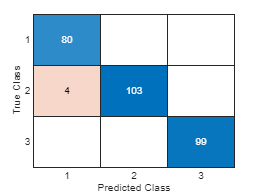

[net, tr] = train(net, data_norm(trainIdx,:)', labels_onehot(:,trainIdx));

Y = net(data_norm(testIdx,:)');
predictedClasses = vec2ind(Y);
trueClasses = vec2ind(labels_onehot(:,testIdx));

% conf matrix
confusionchart(trueClasses, predictedClasses)


% Calculate accuracy
accuracy = sum(predictedClasses == trueClasses) / numel(trueClasses);
fprintf('Classification Accuracy: %.2f%%\n', accuracy * 100);

Classification Accuracy: 98.60%
